# Free-vibration of a plane-stress plate - Modal Analysis

- 2 inputs: B, H

- Output: mode shapes, $\phi$ (1st mode shape only for now)

clear; close all; clc;

## 1. PROBLEM PARAMETERS AND DOMAIN

nNodesX = 8;
nNodesY = 8;
nNodes  = nNodesX * nNodesY;

B_min = 1;  B_max = 3;
H_min = 1;  H_max = 3;
nSamples = 2000;

% Material
E   = 1;
nu  = 0.3;
rho = 1;      % density
t   = 1;      % plate thickness

% Number of modes required
nModes = 3;

% Reference unit mesh
[xGrid, yGrid] = meshgrid(linspace(0,1,nNodesX), linspace(0,1,nNodesY));
coords0 = [xGrid(:), yGrid(:)];

% DOF per node and total DOFs
ndofNode = 2;
nDOF = nNodes * ndofNode;

fprintf('Problem: %d nodes (%dx%d) -> %d DOFs\n', nNodes, nNodesX, nNodesY, nDOF);

Problem: 64 nodes (8x8) -> 128 DOFs


## 2. DATASET CREATION: FEM MODAL ANALYSIS

Xdata   = zeros(2, nSamples);                 % [B; H]
PhiAll  = zeros(nDOF, nModes, nSamples);      % full mode shapes
FreqAll = zeros(nModes, nSamples);            % frequencies in Hz
OmegaAll = zeros(nModes, nSamples);           % circular frequencies rad/s

fprintf('Generating FEM modal dataset (%d samples)...\n', nSamples);

Generating FEM modal dataset (2000 samples)...



tic

for samp = 1:nSamples

    %% Geometry sampling
    B = B_min + (B_max - B_min) * rand();
    H = H_min + (H_max - H_min) * rand();

    Xdata(:,samp) = [B; H];

    % Physical coordinates
    coords = [coords0(:,1)*B, coords0(:,2)*H];

    % %% Assemble stiffness and mass matrices
    % % K = assembleStiffnessQ4(coords, elements, E, nu, t);
    % K = assembleStiffnessQ4(coords, nNodesX, nNodesY, E, nu, t);
    % M = assembleMassQ4(coords, elements, rho, t);

    [K, M] = buildPlaneStressModalFEM(coords, nNodesX, nNodesY, E, nu, rho, t);

    % % % Force exact numerical symmetry to remove roundoff-level asymmetry
    % K = 0.5 * (K + K');
    % M = 0.5 * (M + M');

    if samp == 1
        % Symmetry check
        symErrK = norm(K - K', 'fro') / norm(K, 'fro');
        symErrM = norm(M - M', 'fro') / norm(M, 'fro');

        fprintf('Relative symmetry error K = %.3e\n', symErrK);
        fprintf('Relative symmetry error M = %.3e\n', symErrM);
    end

    % is_K_symmetric = issymmetric(K); 
    % if is_K_symmetric
    %     disp('Matrix K is symmetric.');
    % else
    %     disp('Matrix K is NOT symmetric.');
    % end
    % 
    % is_M_symmetric = issymmetric(M);
    % if is_M_symmetric
    %     disp('Matrix M is symmetric.');
    % else
    %     disp('Matrix M is NOT symmetric.');
    % end
   
    % if samp == 1
    %     disp('Stiffness for geom 1:'); disp(K);
    %     disp('Mass for geom 1:'); disp(M);
    % end

    %% Fixed base: y = 0
    tol = 1e-12;
    baseNodes = find(abs(coords(:,2)) < tol);

    fixedDOFs = reshape([(baseNodes-1)'*ndofNode + 1; (baseNodes-1)'*ndofNode + 2], [], 1);

    freeDOFs = setdiff(1:nDOF, fixedDOFs);

    % fprintf('Number of base nodes: %d (expected %d)\n', length(baseNodes), nNodesX);
    % fprintf('Base node y-coords: '); disp(coords(baseNodes,2)')

    %% Reduced matrices
    Kff = K(freeDOFs, freeDOFs);
    Mff = M(freeDOFs, freeDOFs);

    % if samp == 1
    %     disp('Stiffness for geom 1:'); disp(Kff);
    %     disp('Mass for geom 1:'); disp(Mff);
    % end

    % %% Generalized eigenvalue problem
    % % K phi = omega^2 M phi
    % % option passed to the eigs solver, that the eigenvalue problem is
    % % real-valued therefore since the physical system is real, the mode
    % % shapes should also be real.
    % % But even with this, MATLAB may sometimes return tiny imaginary numerical noise
    
    % opts.isreal = true;
    % opts.issym  = true;
    opts.tol    = 1e-10;
    opts.maxit  = 1000;

    [Phi_f, Lambda] = eigs(Kff, Mff, nModes, 'smallestabs', opts);

    % Remove tiny imaginary numerical parts
    % Phi_f  = real(Phi_f);
    % Lambda = real(Lambda);

    lambda = diag(Lambda);

    % Remove tiny negative roundoff values
    lambda(lambda < 0 & abs(lambda) < 1e-10) = 0;

    omega = sqrt(lambda);
    freq  = omega / (2*pi);

    %% Sort modes by increasing frequency
    [freq, sortIdx] = sort(freq, 'ascend');
    omega = omega(sortIdx);
    Phi_f = Phi_f(:, sortIdx);

    %% Expand to full DOFs
    Phi_full = zeros(nDOF, nModes);
    Phi_full(freeDOFs,:) = Phi_f;

    %% Mass normalization
    for imode = 1:nModes
        modalMass = Phi_full(:,imode)' * M * Phi_full(:,imode);
        Phi_full(:,imode) = Phi_full(:,imode) / sqrt(modalMass);
    end

    % modalMassCheck = Phi_full(:,1)' * M * Phi_full(:,1);
    % disp(modalMassCheck)

    %% Sign correction
    % FEM eigenvectors are arbitrary up to sign.
    % This makes the largest absolute DOF positive.
    for imode = 1:nModes
        [~, idxMax] = max(abs(Phi_full(:,imode)));

        if Phi_full(idxMax,imode) < 0
            Phi_full(:,imode) = -Phi_full(:,imode);
        end
    end

    % Final safety to make sure only real values
    % Phi_full = real(Phi_full);
    % omega = real(omega);
    % freq = real(freq);

    %% Store data
    PhiAll(:,:,samp) = Phi_full;
    FreqAll(:,samp) = freq;
    OmegaAll(:,samp) = omega;

end

Relative symmetry error K = 4.476e-17


Relative symmetry error M = 0.000e+00



disp('FEM modal dataset generated.');

FEM modal dataset generated.


toc

Elapsed time is 19.010433 seconds.



% PhiAll dim: nDOF x nModes x nSamples
disp('PhiAll'); disp (PhiAll)

PhiAll

(:,:,1) =

         0         0         0
         0         0         0
    0.0787    0.0784   -0.1606
    0.0963    0.1336   -0.0090
    0.1598    0.1025   -0.3060
    0.1591    0.2314    0.1040
    0.2528    0.1040   -0.3543
    0.2032    0.3162    0.2771
    0.3507    0.0893   -0.2869
    0.2317    0.3882    0.4582
    0.4482    0.0655   -0.1207
    0.2469    0.4440    0.6060
    0.5404    0.0374    0.1025
    0.2527    0.4802    0.6954
    0.6269    0.0109    0.3406
    0.2541    0.4933    0.7250
         0         0         0
         0         0         0
    0.0600    0.0454   -0.1820
    0.0451    0.1068    0.0653
    0.1473    0.0745   -0.3380
    0.0912    0.2207    0.1446
    0.2431    0.0783   -0.3902
    0.1256    0.3197    0.2417
    0.3443    0.0684   -0.3204
    0.1495    0.4018    0.3421
    0.4445    0.0505   -0.1461
    0.1645    0.4636    0.4278
    0.5385    0.0295    0.0892
    0.1722    0.5021    0.4844
    0.6243    0.0087    0.3309
    0.1751    0.5155


% FreqAll dim: nModes x nSamples
disp('FreqAll'); disp(FreqAll);

FreqAll
    0.0364    0.0225    0.1091    0.0433    0.0360    0.0218    0.0621    0.1029    0.0295    0.0342    0.1248    0.0358    0.0408    0.0673    0.0950    0.1268    0.1107    0.0244    0.0746    0.1295    0.0616    0.0404    0.0440    0.0419    0.0414    0.0357    0.0965    0.0406    0.0760    0.0849    0.0836    0.0404    0.0354    0.0986    0.0647    0.0852    0.0863    0.0746    0.0679    0.0576    0.0311    0.0511    0.0820    0.0422    0.0450    0.0971    0.0371    0.1071    0.0569    0.0480    0.0274    0.0456    0.0361    0.0366    0.0414    0.1076    0.0252    0.0260    0.0291    0.0427    0.0206    0.0228    0.0379    0.0464    0.0300    0.0299    0.0656    0.0837    0.0539    0.0974    0.0509    0.0479    0.1080    0.0911    0.0688    0.1151    0.0361    0.0535    0.0283    0.0989    0.0682    0.0530    0.0814    0.0361    0.1167    0.0576    0.1333    0.0712    0.0415    0.0601    0.0740    0.0936    0.0935    0.0411    0.1154    0.0435    0.0578    0.0701    0.0522  

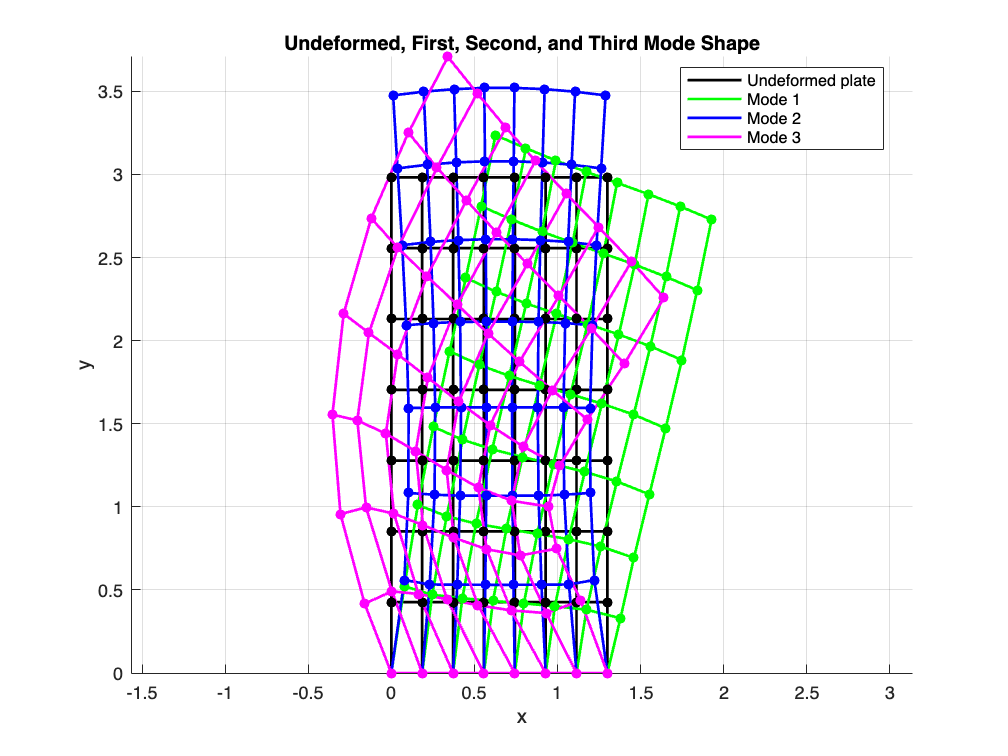

% % Plot
% phi = PhiAll(:,1,1);
% 
% ux = phi(1:2:end);
% uy = phi(2:2:end);
% 
% Ux = reshape(ux, nNodesY, nNodesX);
% Uy = reshape(uy, nNodesY, nNodesX);
% 
% X = reshape(coords(:,1), nNodesY, nNodesX);
% Y = reshape(coords(:,2), nNodesY, nNodesX);
% 
% scale = 0.2;
% 
% figure;
% plot(X, Y, 'k.'); hold on;
% plot(X + scale*Ux, Y + scale*Uy, 'ro');
% axis equal;
% grid on;
% title('Undeformed and deformed first mode shape');
% legend('Original nodes','Mode shape');
% xlim([0, max(X(:))]);
% ylim([0, max(Y(:))]);
% 
% figure;
% plot(X, Y, 'k.'); hold on;
% quiver(X, Y, Ux, Uy);
% axis equal;
% grid on;
% title('First mode shape vector field');
% legend('Original nodes');
% xlim([0, max(X(:))]);
% ylim([0, max(Y(:))]);

% % Plot
% phi = PhiAll(:,1,1);
% 
% ux = phi(1:2:end);
% uy = phi(2:2:end);
% 
% Ux = reshape(ux, nNodesY, nNodesX);
% Uy = reshape(uy, nNodesY, nNodesX);
% 
% X = reshape(coords(:,1), nNodesY, nNodesX);
% Y = reshape(coords(:,2), nNodesY, nNodesX);
% 
% scale = 1.0;
% % scale = 0.2; 
% 
% % Deformed coordinates: scaled to show on figure
% Xd = X + scale*Ux;
% Yd = Y + scale*Uy;
% 
% %% Undeformed and deformed plate shape
% figure;
% hold on;
% 
% % Undeformed plate mesh: black
% plot(X,  Y,  'k-', 'LineWidth', 1.0);   % horizontal/one direction lines
% plot(X', Y', 'k-', 'LineWidth', 1.0);   % vertical/other direction lines
% 
% % Deformed plate mesh: green
% plot(Xd,  Yd,  'g-', 'LineWidth', 1.5);
% plot(Xd', Yd', 'g-', 'LineWidth', 1.5);
% 
% % Old nodes: black
% plot(X, Y, 'ko','MarkerSize', 5,'MarkerFaceColor', 'k');
% 
% % New nodes: green
% plot(Xd, Yd, 'go','MarkerSize', 5,'MarkerFaceColor', 'g');
% 
% axis equal;
% grid on;
% % xlim([0, max(X(:))]);
% % ylim([0, max(Y(:))]);
% 
% xlabel('x');
% ylabel('y');
% title('Undeformed and Deformed First Mode Shape');
% legend('Undeformed plate', 'Deformed plate');
%        % 'Location', 'bottom');

% Plot first and second mode shapes on same figure

% Mode 1
phi1 = PhiAll(:,1,1);

ux1 = phi1(1:2:end);
uy1 = phi1(2:2:end);

Ux1 = reshape(ux1, nNodesY, nNodesX);
Uy1 = reshape(uy1, nNodesY, nNodesX);

% Mode 2
phi2 = PhiAll(:,2,1);

ux2 = phi2(1:2:end);
uy2 = phi2(2:2:end);

Ux2 = reshape(ux2, nNodesY, nNodesX);
Uy2 = reshape(uy2, nNodesY, nNodesX);

% Mode 3
phi3 = PhiAll(:,3,1);

ux3 = phi3(1:2:end);
uy3 = phi3(2:2:end);

Ux3 = reshape(ux3, nNodesY, nNodesX);
Uy3 = reshape(uy3, nNodesY, nNodesX);

% Coordinates
X = reshape(coords(:,1), nNodesY, nNodesX);
Y = reshape(coords(:,2), nNodesY, nNodesX);

scale = 1.0;

% Deformed coordinates
Xd1 = X + scale*Ux1;
Yd1 = Y + scale*Uy1;

Xd2 = X + scale*Ux2;
Yd2 = Y + scale*Uy2;

Xd3 = X + scale*Ux3;
Yd3 = Y + scale*Uy3;

%% Plot
figure;
hold on;

% Undeformed plate mesh: black
h0 = plot(X,  Y,  'k-', 'LineWidth', 1.5);
plot(X', Y', 'k-', 'LineWidth', 1.5);

% Mode 1 deformed mesh: green
h1 = plot(Xd1,  Yd1,  'g-', 'LineWidth', 1.5);
plot(Xd1', Yd1', 'g-', 'LineWidth', 1.5);

% Mode 2 deformed mesh: blue
h2 = plot(Xd2,  Yd2,  'b-', 'LineWidth', 1.5);
plot(Xd2', Yd2', 'b-', 'LineWidth', 1.5);

% Mode 3 deformed mesh: magenta
h3 = plot(Xd3,  Yd3,  'm-', 'LineWidth', 1.5);
plot(Xd3', Yd3', 'm-', 'LineWidth', 1.5);

% Old nodes: black
plot(X, Y, 'ko','MarkerSize', 5,'MarkerFaceColor', 'k');

% Mode 1 nodes: green
plot(Xd1, Yd1, 'go', 'MarkerSize', 5,'MarkerFaceColor', 'g');

% Mode 2 nodes: blue
plot(Xd2, Yd2, 'bo', 'MarkerSize', 5,'MarkerFaceColor', 'b');

% Mode 3 nodes: magenta
plot(Xd3, Yd3, 'mo', 'MarkerSize', 5,'MarkerFaceColor', 'm');

axis equal;
grid on;

xlabel('x');
ylabel('y');
title('Undeformed, First, Second, and Third Mode Shape');

legend([h0(1), h1(1), h2(1), h3(1)], {'Undeformed plate', 'Mode 1', 'Mode 2', 'Mode 3'}, ...
       'Location', 'best');

## 3. DATA PREPARATION AND NORMALIZATION

- Input normalization to [-1,1]

- Output normalization: z-score per DOF

% Input normalization to [-1,1]
% Xdata = [B; H]
Bnorm = 2*(Xdata(1,:) - B_min)/(B_max - B_min) - 1;
Hnorm = 2*(Xdata(2,:) - H_min)/(H_max - H_min) - 1;

Xnorm = [Bnorm; Hnorm];

% Output normalization
% PhiAll size: nDOF x nModes x nSamples; PhiAll_norm will have same size.
epsVal = 1e-8;
mu_Phi    = zeros(nDOF, nModes);
sigma_Phi = zeros(nDOF, nModes);

PhiAll_norm = zeros(size(PhiAll));

% Loop to create phi norm array
for imode = 1:nModes
    % Extract mode imode for all samples; Phi_mode size: nDOF x nSamples
    Phi_mode = squeeze(PhiAll(:,imode,:));

    % Safety check in case squeeze changes dimensions
    if size(Phi_mode,1) ~= nDOF
        Phi_mode = Phi_mode';
    end

    % Row-wise z-score normalization per DOF
    mu_Phi(:,imode)    = mean(Phi_mode, 2); 
    sigma_Phi(:,imode) = std(Phi_mode, 0, 2) + epsVal;

    Phi_mode_norm = (Phi_mode - mu_Phi(:,imode)) ./ sigma_Phi(:,imode);

    % Store back into 3D array
    PhiAll_norm(:,imode,:) = reshape(Phi_mode_norm, nDOF, 1, nSamples);
end

% Frequency normalization
mu_freq = mean(FreqAll, 2);              % nModes x 1
sigma_freq = std(FreqAll, 0, 2) + epsVal;

FreqAll_norm = (FreqAll - mu_freq) ./ sigma_freq;

% Convert to single for speed
Xn = single(Xnorm);
Phin = single(PhiAll_norm);
Freqn = single(FreqAll_norm);

% Create dlarray for input when needed
% For featureInputLayer:C = features; B = batch/sample index

dlXall = dlarray(Xn, "CB");

fprintf('Data preparation complete.\n');

Data preparation complete.



fprintf('Xn size      : %d x %d\n', size(Xn,1), size(Xn,2));

Xn size      : 2 x 2000


fprintf('Phin size    : %d x %d x %d\n', size(Phin,1), size(Phin,2), size(Phin,3));

Phin size    : 128 x 3 x 2000


fprintf('Freqn size   : %d x %d\n', size(Freqn,1), size(Freqn,2));

Freqn size   : 3 x 2000


## 4️. DEFINE SINGLE NETWORK 

- mapping B and H -> mode shapes

tic
% Simple fully-connected network for body force x (NN1)
nOut = nDOF*nModes;

layers = [
    featureInputLayer(2,"Normalization","none") %2 input features: B and H
    fullyConnectedLayer(128)
    % tanhLayer
    reluLayer
    fullyConnectedLayer(128)
    % tanhLayer
    reluLayer
    fullyConnectedLayer(128)
    % tanhLayer
    reluLayer
    fullyConnectedLayer(128)
    % tanhLayer
    reluLayer
    fullyConnectedLayer(128)
    % tanhLayer
    reluLayer
    fullyConnectedLayer(nOut) % out
];
dlnet = dlnetwork(layerGraph(layers));

fprintf('Network defined: input size = 2, output size (DOF*Modes) = %d\n', nOut);

Network defined: input size = 2, output size (DOF*Modes) = 384


## 5. TRAINING - MODAL ANALYSIS NETWORK

- Manual minibatch Adam

% Convert modal output to 2D format for NN training - Phin is turned to Yn
% Phin size: nDOF x nModes x nSamples
% Yn size  : nDOF*nModes x nSamples
Yn = reshape(Phin, nDOF*nModes, nSamples);

fprintf('Training input size  Xn: %d x %d\n', size(Xn,1), size(Xn,2));

Training input size  Xn: 2 x 2000


fprintf('Training output size Yn: %d x %d\n', size(Yn,1), size(Yn,2));

Training output size Yn: 384 x 2000



numEpochs = 2000;
learnRate = 1e-3;
miniBatchSize = 200;

avgGrad = [];
avgSqGrad = [];

numIterationsPerEpoch = ceil(nSamples / miniBatchSize);

disp('🚀 Starting training for modal neural network...');

🚀 Starting training for modal neural network...



for epoch = 1:numEpochs

    idx = randperm(nSamples);

    for it = 1:numIterationsPerEpoch

        batchStart = (it-1)*miniBatchSize + 1;
        batchEnd   = min(it*miniBatchSize, nSamples);
        batchIdx   = idx(batchStart:batchEnd);

        % Form minibatch
        Xbatch = dlarray(Xn(:,batchIdx), "CB");
        Ybatch = dlarray(Yn(:,batchIdx), "CB");

        % Compute loss and gradients
        [loss, gradients] = dlfeval(@modelLoss, dlnet, Xbatch, Ybatch);

        % Adam update
        iteration = (epoch-1)*numIterationsPerEpoch + it;

        [dlnet, avgGrad, avgSqGrad] = adamupdate(dlnet, gradients, avgGrad, avgSqGrad, iteration, learnRate);

    end

    if mod(epoch,100)==0 || epoch==1
        fprintf('Epoch %d/%d - Loss %.3e\n', epoch, numEpochs, gather(extractdata(loss)));
    end

    % Optional learning-rate schedule
    if epoch == round(0.7*numEpochs)
        learnRate = learnRate * 0.2;
        fprintf('Learning rate decreased to %.2e at epoch %d\n', learnRate, epoch);
    end

end

Epoch 1/2000 - Loss 8.643e-01
Epoch 100/2000 - Loss 3.620e-01
Epoch 200/2000 - Loss 3.103e-01
Epoch 300/2000 - Loss 3.331e-01
Epoch 400/2000 - Loss 2.699e-01
Epoch 500/2000 - Loss 2.851e-01
Epoch 600/2000 - Loss 2.546e-01
Epoch 700/2000 - Loss 3.122e-01
Epoch 800/2000 - Loss 3.389e-01
Epoch 900/2000 - Loss 2.512e-01
Epoch 1000/2000 - Loss 2.708e-01
Epoch 1100/2000 - Loss 2.862e-01
Epoch 1200/2000 - Loss 2.312e-01
Epoch 1300/2000 - Loss 2.073e-01
Epoch 1400/2000 - Loss 1.772e-01


Learning rate decreased to 2.00e-04 at epoch 1400


Epoch 1500/2000 - Loss 1.862e-01
Epoch 1600/2000 - Loss 1.740e-01
Epoch 1700/2000 - Loss 1.651e-01
Epoch 1800/2000 - Loss 1.707e-01
Epoch 1900/2000 - Loss 1.893e-01
Epoch 2000/2000 - Loss 1.415e-01



disp('✅ Modal network training completed.');

✅ Modal network training completed.



%% ===============================================================
% SAVE TRAINED MODAL NETWORK
% ===============================================================

save(['modal_net_', num2str(nModes), 'modes_', ...
      num2str(nNodesX),'x',num2str(nNodesY), '.mat'], ...
    'dlnet', ...
    'B_min','B_max','H_min','H_max', ...
    'mu_Phi','sigma_Phi', ...
    'mu_freq','sigma_freq', ...
    'nModes','nNodesX','nNodesY','nDOF','ndofNode', ...
    'E','nu','rho','t');

disp('For training:');

For training:


toc

Elapsed time is 261.377731 seconds.


## 5. INFERENCE + COMPARISON WITH FEM

tic

% Change these parameters for testing
Btest = 1.25;
Htest = 2.0;

fprintf('\nRunning modal inference for B = %.3f, H = %.3f\n', Btest, Htest);


Running modal inference for B = 1.250, H = 2.000



% Normalize geometry input
Bnorm_t = 2*(Btest - B_min)/(B_max - B_min) - 1;
Hnorm_t = 2*(Htest - H_min)/(H_max - H_min) - 1;

dlGeom = dlarray(single([Bnorm_t; Hnorm_t]), "CB");

% Predict normalized mode shapes using NN
% Network output size: nDOF*nModes x 1
phi_norm_dl = predict(dlnet, dlGeom);
phi_norm_vec = double(extractdata(phi_norm_dl));

% Reshape back to: nDOF x nModes
Phi_NN_norm = reshape(phi_norm_vec, nDOF, nModes);

% De-normalize NN mode shapes
% mu_Phi and sigma_Phi size: nDOF x nModes

Phi_NN = zeros(nDOF, nModes);

for imode = 1:nModes
    Phi_NN(:,imode) = Phi_NN_norm(:,imode) .* sigma_Phi(:,imode) + mu_Phi(:,imode);
end

disp('Inference time:')

Inference time:


toc

Elapsed time is 0.708489 seconds.



%% FEM MODAL ANALYSIS - INFERENCE
coords = [coords0(:,1)*Btest, coords0(:,2)*Htest];
[K, M] = buildPlaneStressModalFEM(coords, nNodesX, nNodesY, E, nu, rho, t);

% Force exact numerical symmetry
K = 0.5*(K + K');
M = 0.5*(M + M');

%% Fixed base: y = 0
tol = 1e-12;
baseNodes = find(abs(coords(:,2)) < tol);

fixedDOFs = reshape([(baseNodes-1)'*ndofNode + 1; (baseNodes-1)'*ndofNode + 2], [], 1);

allDOFs = (1:nDOF)';
freeDOFs = setdiff(allDOFs, fixedDOFs);

%% Reduced matrices
Kff = K(freeDOFs, freeDOFs);
Mff = M(freeDOFs, freeDOFs);

%% Generalized eigenvalue problem
% opts.isreal = true;
% opts.issym  = true;
opts.tol    = 1e-10;
opts.maxit  = 1000;

[Phi_f, Lambda] = eigs(Kff, Mff, nModes, 'smallestabs', opts);

% Phi_f  = real(Phi_f);
Lambda = real(Lambda);
lambda = diag(Lambda);

% Remove tiny negative roundoff values
lambda(lambda < 0 & abs(lambda) < 1e-10) = 0;

omega_fem = sqrt(lambda);
freq_fem  = omega_fem/(2*pi);

%% Sort by increasing frequency
[freq_fem, sortIdx] = sort(freq_fem, 'ascend');
omega_fem = omega_fem(sortIdx);
Phi_f = Phi_f(:,sortIdx);

%% Expand to full DOFs
Phi_FEM = zeros(nDOF, nModes);
Phi_FEM(freeDOFs,:) = Phi_f;

%% Mass-normalize FEM modes
for imode = 1:nModes
    modalMass = Phi_FEM(:,imode)' * M * Phi_FEM(:,imode);
    Phi_FEM(:,imode) = Phi_FEM(:,imode) / sqrt(modalMass);
end

%% Sign correction for FEM modes
for imode = 1:nModes
    [~, idxMax] = max(abs(Phi_FEM(:,imode)));

    if Phi_FEM(idxMax,imode) < 0
        Phi_FEM(:,imode) = -Phi_FEM(:,imode);
    end
end

% mass-normalize NN predicted modes
for imode = 1:nModes
    modalMassNN = Phi_NN(:,imode)' * M * Phi_NN(:,imode);
    if modalMassNN > 1e-12
        Phi_NN(:,imode) = Phi_NN(:,imode) / sqrt(modalMassNN);
    end
end

% Sign alignment: make NN mode sign consistent with FEM mode
for imode = 1:nModes
    signCheck = Phi_FEM(:,imode)' * M * Phi_NN(:,imode);
    if signCheck < 0
        Phi_NN(:,imode) = -Phi_NN(:,imode);
    end
end

## 6. PLOTTING


Plotting mode 1: FEM/NN overlay and error shape


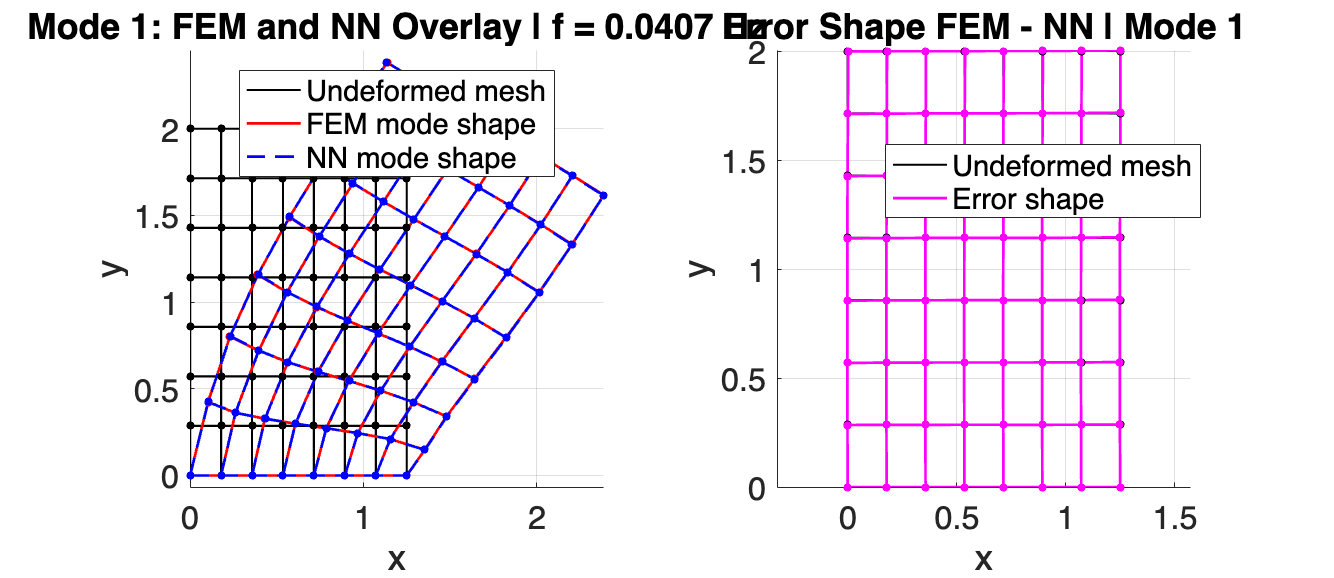


Plotting mode 2: FEM/NN overlay and error shape


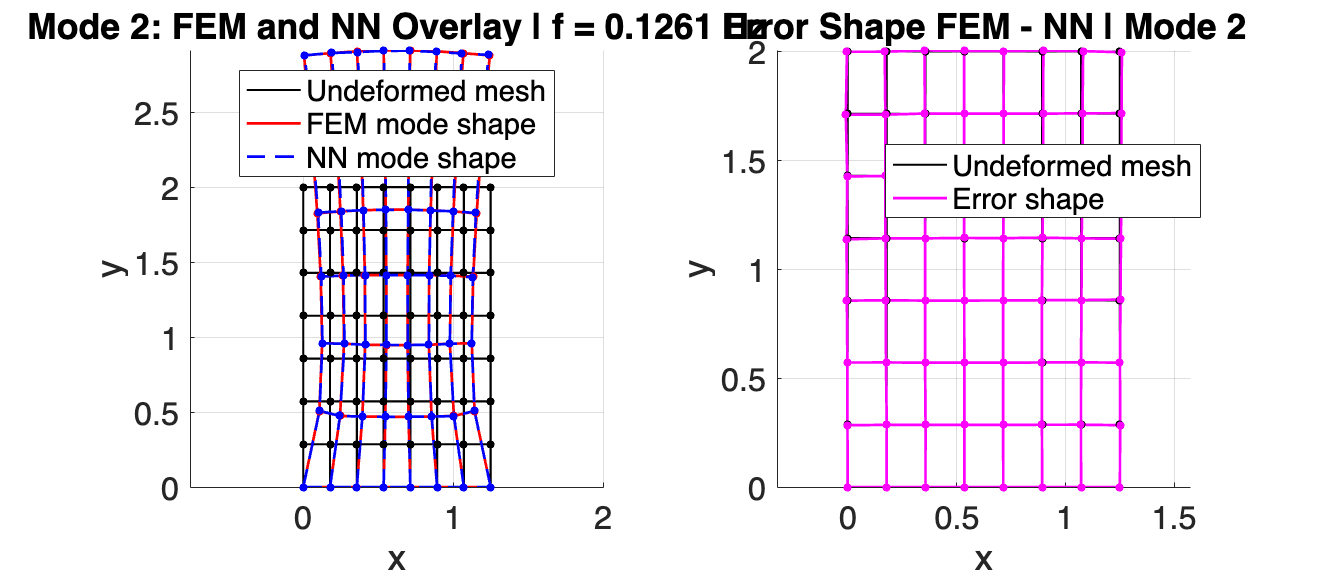


Plotting mode 3: FEM/NN overlay and error shape


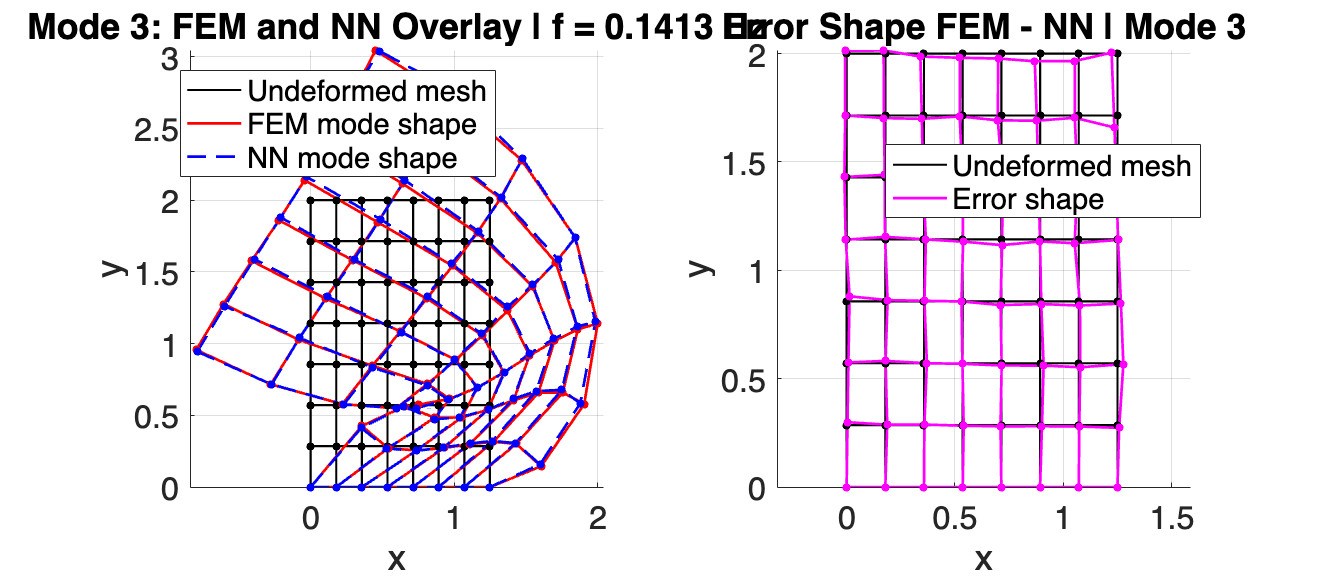

% Xcoords = reshape(coords(:,1), nNodesY, nNodesX);
% Ycoords = reshape(coords(:,2), nNodesY, nNodesX);
% 
% % Plot scale factor for mode shapes
% scale = 1.0;
% 
% % Separate scale for error shape, because error may be small
% errorScale = 1.0;
% 
% for imode = 1:nModes
% 
%     fprintf('\nPlotting mode %d: FEM/NN overlay and error shape\n', imode);
% 
%     %% Extract mode vectors
%     phi_FEM = Phi_FEM(:,imode);
%     phi_NN  = Phi_NN(:,imode);
% 
%     %% Extract x and y components
%     ux_FEM = phi_FEM(1:2:end);
%     uy_FEM = phi_FEM(2:2:end);
% 
%     ux_NN = phi_NN(1:2:end);
%     uy_NN = phi_NN(2:2:end);
% 
%     %% Reshape to grid
%     UxF = reshape(ux_FEM, nNodesY, nNodesX);
%     UyF = reshape(uy_FEM, nNodesY, nNodesX);
% 
%     UxN = reshape(ux_NN, nNodesY, nNodesX);
%     UyN = reshape(uy_NN, nNodesY, nNodesX);
% 
%     %% Deformed coordinates
%     XF_def = Xcoords + scale*UxF;
%     YF_def = Ycoords + scale*UyF;
% 
%     XN_def = Xcoords + scale*UxN;
%     YN_def = Ycoords + scale*UyN;
% 
%     %% Error mode-shape difference
%     UxErr = UxF - UxN;
%     UyErr = UyF - UyN;
% 
%     XE_def = Xcoords + errorScale*UxErr;
%     YE_def = Ycoords + errorScale*UyErr;
% 
%     %% ===========================================================
%     % Figure 1: FEM and NN mode shapes overlaid
%     %% ===========================================================
% 
%     figure('Position',[100 100 900 700]);
%     hold on;
% 
%     % Undeformed mesh
%     h0 = plot(Xcoords,  Ycoords,  'k-', 'LineWidth', 1.2);
%     plot(Xcoords', Ycoords', 'k-', 'LineWidth', 1.2);
% 
%     % FEM deformed mesh
%     h1 = plot(XF_def,  YF_def,  'r-', 'LineWidth', 1.5);
%     plot(XF_def', YF_def', 'r-', 'LineWidth', 1.5);
% 
%     % NN deformed mesh
%     h2 = plot(XN_def,  YN_def,  'b--', 'LineWidth', 1.5);
%     plot(XN_def', YN_def', 'b--', 'LineWidth', 1.5);
% 
%     % Optional nodes
%     plot(Xcoords, Ycoords, 'ko', ...
%         'MarkerSize', 4, 'MarkerFaceColor', 'k');
% 
%     plot(XF_def, YF_def, 'ro', ...
%         'MarkerSize', 4, 'MarkerFaceColor', 'r');
% 
%     plot(XN_def, YN_def, 'bo', ...
%         'MarkerSize', 4, 'MarkerFaceColor', 'b');
% 
%     axis equal;
%     grid on;
%     xlabel('x');
%     ylabel('y');
% 
%     title(['FEM and NN Mode Shape Overlay - Mode ', num2str(imode), ...
%            ' | f = ', num2str(freq_fem(imode),'%.4f'), ' Hz']);
% 
%     legend([h0(1), h1(1), h2(1)], ...
%         {'Undeformed mesh','FEM mode shape','NN mode shape'}, ...
%         'Location','best');
% 
%     %% ===========================================================
%     % Figure 2: Error shape FEM - NN
%     %% ===========================================================
% 
%     figure('Position',[150 150 900 700]);
%     hold on;
% 
%     % Undeformed mesh
%     h0 = plot(Xcoords,  Ycoords,  'k-', 'LineWidth', 1.2);
%     plot(Xcoords', Ycoords', 'k-', 'LineWidth', 1.2);
% 
%     % Error deformed mesh
%     hE = plot(XE_def,  YE_def,  'm-', 'LineWidth', 1.5);
%     plot(XE_def', YE_def', 'm-', 'LineWidth', 1.5);
% 
%     % Optional nodes
%     plot(Xcoords, Ycoords, 'ko', ...
%         'MarkerSize', 4, 'MarkerFaceColor', 'k');
% 
%     plot(XE_def, YE_def, 'mo', ...
%         'MarkerSize', 4, 'MarkerFaceColor', 'm');
% 
%     axis equal;
%     grid on;
%     xlabel('x');
%     ylabel('y');
% 
%     title(['Error Shape FEM - NN | Mode ', num2str(imode)]);
% 
%     legend([h0(1), hE(1)], ...
%         {'Undeformed mesh','Error shape FEM - NN'}, ...
%         'Location','best');
% 
% end
% 
% % Error calculation for each mode
% fprintf('\n========== Modal prediction errors ==========\n');
% 
% RMSE_modes   = zeros(nModes,1);
% relL2_modes  = zeros(nModes,1);
% relInf_modes = zeros(nModes,1);
% MAC_modes    = zeros(nModes,1);
% 
% for imode = 1:nModes
% 
%     phi_FEM = Phi_FEM(:,imode);
%     phi_NN  = Phi_NN(:,imode);
% 
%     e = phi_FEM - phi_NN;
% 
%     RMSE_modes(imode)   = norm(e) / sqrt(numel(e));
%     relL2_modes(imode)  = norm(e) / norm(phi_FEM);
%     relInf_modes(imode) = norm(e, Inf) / norm(phi_FEM, Inf);
% 
%     % Modal Assurance Criterion: similarity measure between two mode shapes
%     MAC_modes(imode) = abs(phi_FEM' * M * phi_NN)^2 / ...
%         ((phi_FEM' * M * phi_FEM) * (phi_NN' * M * phi_NN));
% 
%     fprintf('Mode %d:\n', imode);
%     fprintf('  FEM frequency            : %.6e Hz\n', freq_fem(imode));
%     fprintf('  RMSE                     : %.3e\n', RMSE_modes(imode));
%     fprintf('  Relative L2 error        : %.3e\n', relL2_modes(imode));
%     fprintf('  Relative Infinity error  : %.3e\n', relInf_modes(imode));
%     fprintf('  MAC                      : %.6f\n', MAC_modes(imode));
% 
% end
% 
% disp('Inference and modal comparison completed.');
% toc

% Global text formatting configuration
set(groot, ...
    'DefaultAxesFontSize', 18, ...     % For ticks, x/y/z labels
    'DefaultTextFontSize', 20, ...     % For manually added text objects
    'DefaultLegendFontSize', 20);      % For graph legends


%% ---------------------------------------------------------------
% Plot mode-shape overlay and corresponding error shape
% One figure per mode:
%   subplot 1: FEM + NN mode-shape overlay
%   subplot 2: Error shape FEM - NN
% ---------------------------------------------------------------

Xcoords = reshape(coords(:,1), nNodesY, nNodesX);
Ycoords = reshape(coords(:,2), nNodesY, nNodesX);

% Plot scale factor for mode shapes
scale = 1.0;

% Separate scale for error shape, because error may be small
errorScale = 1.0;

for imode = 1:nModes

    fprintf('\nPlotting mode %d: FEM/NN overlay and error shape\n', imode);

    %% Extract mode vectors
    phi_FEM = Phi_FEM(:,imode);
    phi_NN  = Phi_NN(:,imode);

    %% Extract x and y components
    ux_FEM = phi_FEM(1:2:end);
    uy_FEM = phi_FEM(2:2:end);

    ux_NN = phi_NN(1:2:end);
    uy_NN = phi_NN(2:2:end);

    %% Reshape to grid
    UxF = reshape(ux_FEM, nNodesY, nNodesX);
    UyF = reshape(uy_FEM, nNodesY, nNodesX);

    UxN = reshape(ux_NN, nNodesY, nNodesX);
    UyN = reshape(uy_NN, nNodesY, nNodesX);

    %% Deformed coordinates for FEM and NN
    XF_def = Xcoords + scale*UxF;
    YF_def = Ycoords + scale*UyF;

    XN_def = Xcoords + scale*UxN;
    YN_def = Ycoords + scale*UyN;

    %% Error shape FEM - NN
    UxErr = UxF - UxN;
    UyErr = UyF - UyN;

    XE_def = Xcoords + errorScale*UxErr;
    YE_def = Ycoords + errorScale*UyErr;

    %% Error values for reporting
    e = phi_FEM - phi_NN;

    RMSE   = norm(e) / sqrt(numel(e));
    relL2  = norm(e) / norm(phi_FEM);
    relInf = norm(e, Inf) / norm(phi_FEM, Inf);

    MAC = abs(phi_FEM' * M * phi_NN)^2 / ...
        ((phi_FEM' * M * phi_FEM) * (phi_NN' * M * phi_NN));

    %% ===========================================================
    % Figure: overlay and error side by side
    %% ===========================================================

    figure('Position',[100 100 1500 650]);

    %% -----------------------------------------------------------
    % Subplot 1: FEM and NN mode-shape overlay
    %% -----------------------------------------------------------

    subplot(1,2,1);
    hold on;

    % Undeformed mesh
    h0 = plot(Xcoords,  Ycoords,  'k-', 'LineWidth', 1.2);
    plot(Xcoords', Ycoords', 'k-', 'LineWidth', 1.2);

    % FEM deformed mesh
    h1 = plot(XF_def,  YF_def,  'r-', 'LineWidth', 1.5);
    plot(XF_def', YF_def', 'r-', 'LineWidth', 1.5);

    % NN deformed mesh
    h2 = plot(XN_def,  YN_def,  'b--', 'LineWidth', 1.5);
    plot(XN_def', YN_def', 'b--', 'LineWidth', 1.5);

    % Nodes
    plot(Xcoords, Ycoords, 'ko', ...
        'MarkerSize', 4, 'MarkerFaceColor', 'k');

    plot(XF_def, YF_def, 'ro', ...
        'MarkerSize', 4, 'MarkerFaceColor', 'r');

    plot(XN_def, YN_def, 'bo', ...
        'MarkerSize', 4, 'MarkerFaceColor', 'b');

    axis equal;
    grid on;
    xlabel('x');
    ylabel('y');

    title(['Mode ', num2str(imode), ...
           ': FEM and NN Overlay | f = ', ...
           num2str(freq_fem(imode),'%.4f'), ' Hz']);

    legend([h0(1), h1(1), h2(1)], ...
        {'Undeformed mesh','FEM mode shape','NN mode shape'}, ...
        'Location','best');

    %% -----------------------------------------------------------
    % Subplot 2: Error shape FEM - NN
    %% -----------------------------------------------------------

    subplot(1,2,2);
    hold on;

    % Undeformed mesh
    h0e = plot(Xcoords,  Ycoords,  'k-', 'LineWidth', 1.2);
    plot(Xcoords', Ycoords', 'k-', 'LineWidth', 1.2);

    % Error deformed mesh
    hE = plot(XE_def,  YE_def,  'm-', 'LineWidth', 1.5);
    plot(XE_def', YE_def', 'm-', 'LineWidth', 1.5);

    % Nodes
    plot(Xcoords, Ycoords, 'ko', ...
        'MarkerSize', 4, 'MarkerFaceColor', 'k');

    plot(XE_def, YE_def, 'mo', ...
        'MarkerSize', 4, 'MarkerFaceColor', 'm');

    axis equal;
    grid on;
    xlabel('x');
    ylabel('y');

    title(['Error Shape FEM - NN | Mode ', num2str(imode)]);

    legend([h0e(1), hE(1)], ...
        {'Undeformed mesh','Error shape'}, ...
        'Location','best');

    % %% Overall title
    % sgtitle(['Mode ', num2str(imode), ...
    %     ' | RMSE = ', num2str(RMSE,'%.3e'), ...
    %     ' | Rel. L2 = ', num2str(relL2,'%.3e'), ...
    %     ' | MAC = ', num2str(MAC,'%.4f')]);

end


%% ---------------------------------------------------------------
% Error calculation for each mode
% ---------------------------------------------------------------

fprintf('\n========== Modal prediction errors ==========\n');


========== Modal prediction errors ==========



RMSE_modes   = zeros(nModes,1);
relL2_modes  = zeros(nModes,1);
relInf_modes = zeros(nModes,1);
MAC_modes    = zeros(nModes,1);

for imode = 1:nModes

    phi_FEM = Phi_FEM(:,imode);
    phi_NN  = Phi_NN(:,imode);

    e = phi_FEM - phi_NN;

    RMSE_modes(imode)   = norm(e) / sqrt(numel(e));
    relL2_modes(imode)  = norm(e) / norm(phi_FEM);
    relInf_modes(imode) = norm(e, Inf) / norm(phi_FEM, Inf);

    % Modal Assurance Criterion
    MAC_modes(imode) = abs(phi_FEM' * M * phi_NN)^2 / ...
        ((phi_FEM' * M * phi_FEM) * (phi_NN' * M * phi_NN));

    fprintf('Mode %d:\n', imode);
    fprintf('  FEM frequency            : %.6e Hz\n', freq_fem(imode));
    fprintf('  RMSE                     : %.3e\n', RMSE_modes(imode));
    fprintf('  Relative L2 error        : %.3e\n', relL2_modes(imode));
    fprintf('  Relative Infinity error  : %.3e\n', relInf_modes(imode));
    fprintf('  MAC                      : %.6f\n', MAC_modes(imode));

end

Mode 1:


  FEM frequency            : 4.072486e-02 Hz


  RMSE                     : 1.194e-03


  Relative L2 error        : 2.525e-03


  Relative Infinity error  : 2.755e-03


  MAC                      : 0.999995


Mode 2:


  FEM frequency            : 1.260663e-01 Hz


  RMSE                     : 2.958e-03


  Relative L2 error        : 6.593e-03


  Relative Infinity error  : 1.037e-02


  MAC                      : 0.999968


Mode 3:


  FEM frequency            : 1.412901e-01 Hz


  RMSE                     : 1.258e-02


  Relative L2 error        : 2.602e-02


  Relative Infinity error  : 5.294e-02


  MAC                      : 0.999450



disp('Plotting completed.');

Plotting completed.


toc

Elapsed time is 443.265090 seconds.


## Local functions

function [K, M] = buildPlaneStressModalFEM(coords, nx, ny, E, nu, rho, t)
    % Structured mesh of 4-node bilinear quadrilateral elements
    % Consistent with previous buildPlaneStressFEM node ordering:
    %
    % n1 = (ix-1)*ny + jy;
    % n2 = ix*ny + jy;
    % n3 = ix*ny + (jy+1);
    % n4 = (ix-1)*ny + (jy+1);

    nNodes = nx*ny;
    nElemX = nx-1; nElemY = ny-1;
    nElem = nElemX * nElemY;
    ndofNode = 2;
    nDOF = nNodes * ndofNode; %total dof of system

    % element connectivity matrix
    %(ix, iy) is one quadrilateral element
    conn = zeros(nElem,4);
    for ix = 1:nElemX
        for jy = 1:nElemY
            n1 = (ix-1)*ny + jy;
            n2 = ix*ny + jy;
            n3 = ix*ny + (jy+1);
            n4 = (ix-1)*ny + (jy+1);
            e = (ix-1)*nElemY + jy; %This converts the 2D element index (ix, jy) into a single element number
            conn(e,:) = [n1 n2 n3 n4]; %Element e connects nodes n1, n2, n3, n4
        end
    end

    %% Initialize global matrices
    K = zeros(nDOF, nDOF);
    M = zeros(nDOF, nDOF);

    % Plane stress constitutive matrix
    D = E / (1 - nu^2) * [1, nu, 0;
                          nu, 1, 0;
                          0, 0, (1-nu)/2];

    %% 2x2 Gauss quadrature
    gp  = [-1/sqrt(3), 1/sqrt(3)];
    wgp = [1, 1];

    %% Element loop
    for e = 1:nElem
        nodes = conn(e,:);
        xe = coords(nodes,1);
        ye = coords(nodes,2);
        
        %element stiffness and force matrix
        Ke = zeros(8,8);
        Me = zeros(8,8);

        %% Reduced integration shear row at element center
        xi = 0; eta = 0;
        % [~, dNdxi0, dNdeta0] = shape4(xi, eta);
        [N0, dNdxi0, dNdeta0] = shape4(xi,eta);
        J0 = [dNdxi0'; dNdeta0'] * [xe, ye];
        detJ0 = det(J0);
        invJ0 = inv(J0);

        if detJ0 <= 0
            error('Element %d has non-positive detJ at center: %.3e', e, detJ0);
        end

        dN0 = [dNdxi0, dNdeta0] * invJ0;

        B0 = zeros(3,8);
        for a = 1:4
            dNx = dN0(a,1);
            dNy = dN0(a,2);
            col = (a-1)*2;
            B0(1, col + 1) = dNx;
            B0(2, col + 2) = dNy;
            B0(3, col + 1) = dNy;
            B0(3, col + 2) = dNx;
        end

        %% Gauss integration loop
        for i = 1:2
            for j = 1:2
                xi  = gp(i); eta = gp(j);
                [N, dNdxi, dNdeta] = shape4(xi, eta);
                J = [dNdxi'; dNdeta'] * [xe, ye];
                detJ = det(J);
                invJ = inv(J);

                if detJ <= 0
                    error('Element %d has non-positive detJ: %.3e', e, detJ);
                end

                dN = [dNdxi, dNdeta] * invJ;

                %% Strain-displacement matrix
                B = zeros(3,8);
                for a = 1:4
                    dNx = dN(a,1);
                    dNy = dN(a,2);
                    col = (a-1)*2;
                    B(1, col + 1) = dNx;
                    B(2, col + 2) = dNy;
                    B(3, col + 1) = dNy;
                    B(3, col + 2) = dNx;
                end

                % replace shear row with reduced-integration shear row
                B(3,:) = B0(3,:);

                % Element stiffness
                Ke = Ke + (B' * D * B) * t * detJ * wgp(i) * wgp(j);

                %% Shape function matrix for mass
                Nmat = zeros(2,8);
                for a = 1:4
                    Nmat(1, (a-1)*2 + 1) = N(a);
                    Nmat(2, (a-1)*2 + 2) = N(a);
                end
                %% Element  mass
                Me = Me + rho * (Nmat' * Nmat) * t * detJ * wgp(i) * wgp(j);
            end
        end

        %% Global DOF mapping
        gdofs = zeros(8,1);
        for a = 1:4
            node = nodes(a);
            gdofs((a-1)*2 + (1:2)) = (node-1)*2 + (1:2);
        end
        %% Assembly
        K(gdofs, gdofs) = K(gdofs, gdofs) + Ke;
        M(gdofs, gdofs) = M(gdofs, gdofs) + Me;
    end
end

function [N, dNdxi, dNdeta] = shape4(xi,eta)
    N = 0.25*[(1-xi)*(1-eta);
              (1+xi)*(1-eta);
              (1+xi)*(1+eta);
              (1-xi)*(1+eta)];
    dNdxi  = 0.25*[-(1-eta); (1-eta); (1+eta); -(1+eta)];
    dNdeta = 0.25*[-(1-xi); -(1+xi); (1+xi);  (1-xi)];
end

function [loss,gradients] = modelLoss(dlnet,X,Y)
    % Simple MSE loss for single network
    Ypred = forward(dlnet,X);
    loss = mean((Ypred - Y).^2,'all');
    gradients = dlgradient(loss, dlnet.Learnables);
end